# **[2024년 1학기 디지털제어 MATLAB/Simulink 예제] Ch. 4-a. 펄스 전달함수의 이해**

- 본 파일은 2024년 1학기 개설된 서울시립대학교 전자전기컴퓨터공학부 **디지털제어** 교과목 수업의 보조 자료로 활용하기 위해 제작되었습니다.

- **작성자** : 서울시립대학교 전자전기컴퓨터공학부 박경훈 교수(gyunghoon.park@uos.ac.kr), 김준수 박사과정생

- **교과목 github 페이지 **: [https://github.com/CDSL-UoS/Course_Digital-Control_2024](https://github.com/CDSL-UoS/Course_Digital-Control_2024) 

- **교과목 notion 페이지** : [https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4](https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4) 

- **참고사항** : 2023b version 이상의 MATLAB/Simulink 환경에서 구동을 권장합니다. (2023a 이하 version 사용 시 Simulink 파일 등이 원활히 작동되지 않을 수 있습니다.)

아래 예제를 실행하기에 앞서, 다음 코드를 실행하여 작업 공간 등을 초기화합시다.

clc; clear all; close all;      % Initialization

### Topic 1 : `c2d` 함수를 이용한 펄스 전달함수 계산

Topic 1에서는 연속 시간 시스템을 이산 시간 시스템으로 변환하는 `c2d` 함수를 이용하여 펄스 전달함수를 계산하도록 합니다. 

설명의 편의를 위해, 4-a에서는 아래의 간단한 1차 시스템을 제어 대상인 연속 시간 플랜트(plant)로 생각합니다.


$$G_p(s)=\frac{1}{s+2}$$


num_Gp_tf = [1];
den_Gp_tf = [1 2];
Gp_tf_1 = tf(num_Gp_tf, den_Gp_tf);

그리고 샘플링 주기 $T$는 $0.2~{\rm sec}$로 정합니다. 

T = 0.2;

위의 연속 시간 플랜트와 0차 홀드, 샘플러를 결합한 개루프 샘플 데이터 시스템의 전달함수를 의미하는 펄스 전달함수는 다음과 같습니다. 


$$G^d(z)=\mathcal{Z}[G(s)],\quad G(s)=\frac{1}{s+2}\frac{1-e^{-Ts}}{s}$$


펄스 전달함수 $G^d(z)$는 `c2d` 함수에 연속 시간 플랜트 $G_p(s)$를 입력하여 얻을 수 있습니다. 

Gd_tf_1 = c2d(Gp_tf_1,T,'zoh')

Gd_tf_1 =
 
    0.1648
  ----------
  z - 0.6703
 
샘플 시간: 0.2 seconds
이산시간 전달 함수입니다.
모델 속성


`tf` 모델 객체로 표현된 전달함수의 분자식, 분모식 계수 벡터들은 `tfdata`라는 함수를 이용하여 추출해낼 수 있습니다.

(`tfdata` 함수는 `cell` 객체로 분자식, 분모식 계수 벡터를 출력하기 때문에, 이를 고려합니다.)  

[num_Gd_tf_1, den_Gd_tf_1] = tfdata(Gd_tf_1);
num_Gd_tf_1 = num_Gd_tf_1{1};
den_Gd_tf_1 = den_Gd_tf_1{1};

### Topic 2 : `iztrans` 함수를 이용한 펄스 전달함수 계산

Topic 2에서는 위와 동일한 샘플 데이터 시스템의 펄스 전달함수 $G^d(z)$를 `ilaplace` 함수와 `ztrans` 함수 등을 이용하여 계산하고자 합니다. 

이를 위해 아래의 `symbolic` 변수들을 정의합니다.

syms s k t z

Starred 변환의 성질을 생각해볼 때 $G^*(s)$를 다음과 같이 얻습니다. 


$$G^*(s)= \left[\frac{1}{s+2}\frac{1-e^{-Ts}}{s}\right]^* = \left[ \frac{1}{s(s+2)} \right]^* (1-e^{-Ts}) $$


 따라서 이번 예제에서 계산해야 할 펄스 전달함수는 아래와 같이 계산됩니다. 


$$G^d(z) = G^*(s)\bigg|_{e^{Ts} =z} = \mathcal{Z}\left[ \frac{1}{s(s+2)} \right] (1-z^{-1})$$


h_t  = ilaplace(1/(s*(s+2)));
hd_k = subs(h_t,t,k*T);
Gd_tf_2 = ztrans(hd_k,k,z) * (1-z^-1);
Gd_tf_2 = simplify(Gd_tf_2)

$$Gd\_tf\_2 = \frac{{\mathrm{e}}^{2/5}-1}{2\,z\,{\mathrm{e}}^{2/5}-2}$$

이제 아래의 코드를 이용하여 symbolic 표현법으로 작성된 전달함수의 분자식, 분모식 계수 벡터들을 뽑아냅시다. 

[num_Gd_tf_2, den_Gd_tf_2] = numden(Gd_tf_2);
num_Gd_tf_2 = double(coeffs(num_Gd_tf_2, 'z', 'all'));
den_Gd_tf_2 = double(coeffs(den_Gd_tf_2, 'z', 'all'));

num_Gd_tf_2 = num_Gd_tf_2/den_Gd_tf_2(1);
den_Gd_tf_2 = den_Gd_tf_2/den_Gd_tf_2(1);

### Topic 3 : Simulink 환경에서의 단위 계단 응답 구현

Topic 3에서는 앞서 계산한 펄스 전달함수와 샘플 데이터 시스템을 모두 Simulink 환경에서 구현하고, 이들의 단위 계단 응답을 비교합니다. 

미리 작성된 Simulink 파일을 열어봅시다.

open('sim_topic3.slx');

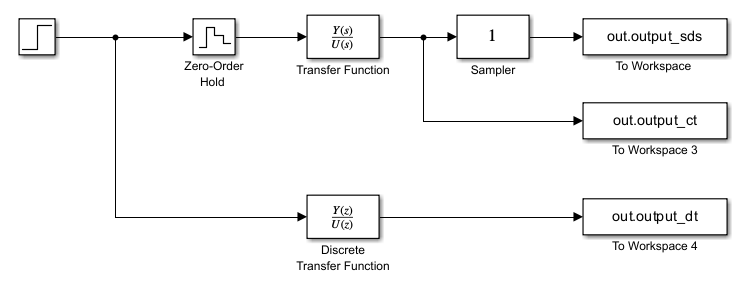

위의 파일에서 샘플 데이터 시스템은 0차 홀드, 연속 시간 전달함수, 샘플러를 직렬로 연결한 시스템이며, 그 아래의 이산 시간 전달함수는 펄스 전달함수를 구현한 것입니다. 

이 둘은 이산 시간에서 서로 등가적인 입출력 관계가 있으리라 예상됩니다. 실제로 모의실험을 통해 이를 확인해봅시다.

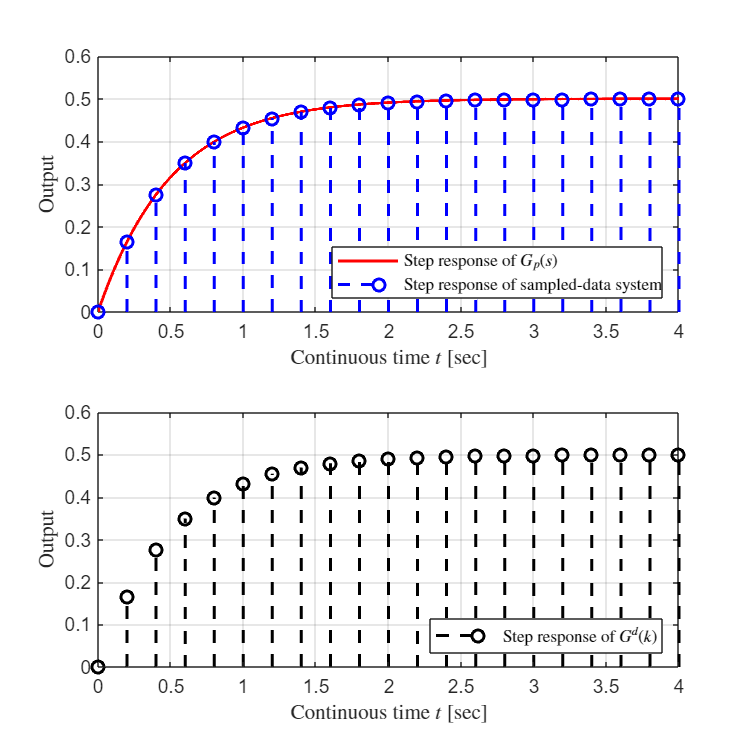

T_sim = 10;
dt_sim = 0.001;             % Simulation의 sampling period

sim('sim_topic3.slx');
simout = ans;
time_dt_sim3 = simout.time_dt;
time_ct_sim3 = simout.time_ct;
output_dt_sim3 = simout.output_dt;
output_ct_sim3 = simout.output_ct;
output_sds_sim3 = simout.output_sds;

f = figure();
f.Position = [100 100 500 500];
subplot(2,1,1)
    plot(time_ct_sim3,output_ct_sim3,'r','LineWidth',1.5);
    hold on;
    stem(time_dt_sim3,output_sds_sim3,'--b','LineWidth',1.5);
    grid on;
    xlabel('Continuous time $t$ [sec]','Interpreter','latex');
    ylabel('Output','Interpreter','latex');
    xlim([0 4]); 
    ylim([0 0.6]);
    legend('Step response of $G_p(s)$','Step response of sampled-data system','Interpreter','latex','Location','southeast'); 
subplot(2,1,2)
    stem(time_dt_sim3,output_dt_sim3,'--k','LineWidth',1.5);
    grid on;
    xlabel('Continuous time $t$ [sec]','Interpreter','latex');
    ylabel('Output','Interpreter','latex');
    xlim([0 4]); 
    ylim([0 0.6]);
    legend('Step response of $G^d(k)$','Interpreter','latex','Location','southeast'); 